# **Efficient Frontier for 8 Assets**

The 72 monthly returns for 8 assets is saved in the file '8AssetsData.mat'. The monthly returns of 8 assets (SPY, GOVT, EEMV, CME, BR, CBOE, ICE, ACN) between jan 2014 and december 2019 is used. The monthly returns are calculated using adjusted colsing price of the assets on the first and last trading day of each month. Loading the file '8AssetsData' loads the variale 'returns' in the current workspace.

load('8AssetsData')

returns =    -0.0259    0.0123   -0.0571   -0.0410   -0.0764    0.0204   -0.0704   -0.0154
    0.0696   -0.0012    0.0598    0.0087    0.0703    0.1034    0.0265    0.0674
    0.0154   -0.0057    0.0419    0.0050   -0.0144    0.0217   -0.0430   -0.0337
    0.0003    0.0078    0.0087   -0.0312    0.0116   -0.0526    0.0585    0.0207
    0.0231    0.0073    0.0205    0.0187    0.0730   -0.0486   -0.0442    0.0202
    0.0195   -0.0012    0.0213   -0.0072    0.0073   -0.0207   -0.0102   -0.0053
   -0.0200         0    0.0023    0.0416   -0.0317   -0.0104    0.0317   -0.0242
    0.0426    0.0085    0.0235    0.0319    0.0499    0.0710   -0.0165    0.0300
   -0.0133   -0.0020   -0.0458    0.0483   -0.0212    0.0024    0.0538    0.0025
    0.0376    0.0060    0.0242    0.0555    0.0670    0.1029    0.0732    0.0314


# Computation of parameters

% arithmatic average of each stock
avg_return = mean(returns)

avg_return =     0.0095    0.0025    0.0030    0.0154    0.0179    0.0132    0.0143    0.0165



% geometric expected return of each stock
GM_return = nthroot(prod(returns + 1), 72) - 1

GM_return =     0.0090    0.0024    0.0025    0.0145    0.0166    0.0116    0.0133    0.0154



% covariance between assets
cov_mat = cov(returns,1)

cov_mat =     0.0010   -0.0001    0.0006    0.0002    0.0008    0.0002    0.0004    0.0011
   -0.0001    0.0001    0.0000   -0.0001    0.0001    0.0000   -0.0001   -0.0000
    0.0006    0.0000    0.0010   -0.0002    0.0006   -0.0001   -0.0000    0.0005
    0.0002   -0.0001   -0.0002    0.0019    0.0008    0.0010    0.0009    0.0002
    0.0008    0.0001    0.0006    0.0008    0.0027    0.0004    0.0006    0.0011
    0.0002    0.0000   -0.0001    0.0010    0.0004    0.0033    0.0007    0.0003
    0.0004   -0.0001   -0.0000    0.0009    0.0006    0.0007    0.0020    0.0008
    0.0011   -0.0000    0.0005    0.0002    0.0011    0.0003    0.0008    0.0021



% standard deviation of assets
stddev = sqrt(diag(cov_mat)')

stddev =     0.0322    0.0094    0.0317    0.0435    0.0522    0.0574    0.0443    0.0455


# Mean-Variance Optimization 

## Minimum variance point

H = cov_mat;
c = [0 0 0 0 0 0 0 0]';
A = []; % find minimum variance point using no contraint for return
b = [];
Aeq = [1 1 1 1 1 1 1 1];
beq = [1];
ub = [inf; inf; inf; inf; inf; inf; inf; inf;];
lb = [-inf; -inf; -inf; -inf; -inf; -inf; -inf; -inf;]; %with short selling
lb_without = [0; 0; 0; 0; 0; 0; 0; 0;]; % without short selling
% turn off the exit message
x0 = [];
options =  optimoptions(@quadprog,'Display','off');

#### With short selling

% minimum variance point with short selling
[w_ss, fval_min_ss] = quadprog(H, c, A, b, Aeq, beq, lb, ub, x0,options)

w_ss =     0.2232
    0.8601
   -0.0299
    0.0588
   -0.0693
   -0.0233
    0.0315
   -0.0512


fval_min_ss = 2.1941e-05


% portfolio return at min variance point with short selling
r_ss = GM_return * w_ss

r_ss = 0.0031

#### Without short selling

% minimum variance point without short selling
[w_no_ss, fval_min_no_ss] = quadprog(H, c, A, b, Aeq, beq, lb_without, ub, x0,options)

w_no_ss =     0.1129
    0.8274
    0.0005
    0.0313
    0.0000
    0.0001
    0.0277
    0.0000


fval_min_no_ss = 2.9326e-05


% portfolio return at min variance point without short selling
r_no_ss = GM_return * w_no_ss

r_no_ss = 0.0038

## Vary portfolio return (goal) to get points on efficient frontiers

A = -GM_return;

#### with short selling

weights_ss = [];
fvals_ss = [];
r_goal_ss = 0.0035:0.0005:0.010;
% portfolio returns
r_goal_ss = [r_ss r_goal_ss]

r_goal_ss =     0.0031    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100


for b = r_goal_ss
    [w_min, fval_min] = quadprog(H, c, A, -b, Aeq, beq, lb, ub, x0,options);  
    weights_ss = [weights_ss, w_min];
    fvals_ss(end + 1) = fval_min;
end
% portfolio standard deviations
volatility_ss = sqrt(2*fvals_ss)

volatility_ss =     0.0066    0.0067    0.0071    0.0076    0.0083    0.0092    0.0101    0.0111    0.0122    0.0133    0.0144    0.0156    0.0168    0.0180    0.0192


#### without short selling

weights_no_ss = [];
fvals_no_ss = [];
r_goal_no_ss = 0.0040:0.0005:0.010;
% portfolio returns
r_goal_no_ss = [r_no_ss r_goal_no_ss]

r_goal_no_ss =     0.0038    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100


for b = r_goal_no_ss
    [w_min, fval_min] = quadprog(H, c, A, -b, Aeq, beq, lb_without, ub, x0,options);  
    weights_no_ss = [weights_no_ss, w_min];
    fvals_no_ss(end + 1) = fval_min;
end
% portfolio standard deviations
volatility_no_ss = sqrt(2*fvals_no_ss)

volatility_no_ss =     0.0077    0.0077    0.0080    0.0086    0.0094    0.0103    0.0113    0.0124    0.0135    0.0147    0.0159    0.0171    0.0183    0.0196


# Plot efficient frontier

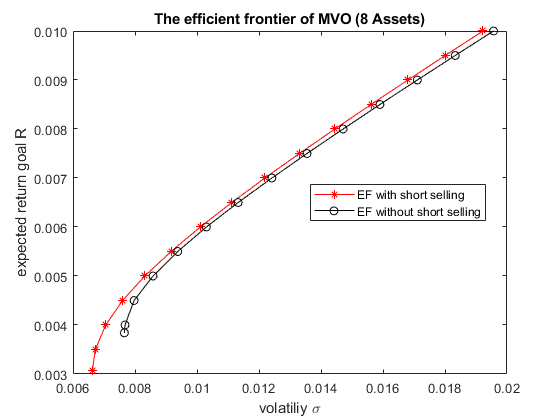

%plot efficient frontier with short selling and without short selling
figure
plot(volatility_ss, r_goal_ss,'r-*')
hold on 
plot(volatility_no_ss, r_goal_no_ss, 'k-o' )
hold off
legend({'EF with short selling', 'EF without short selling'}, 'Location','best')
title('The efficient frontier of MVO (8 Assets)')
xlabel('volatiliy \sigma')
ylabel('expected return goal R')
ytickformat('%.3f')
ax = gca;
ax.YAxis.Exponent = 0;